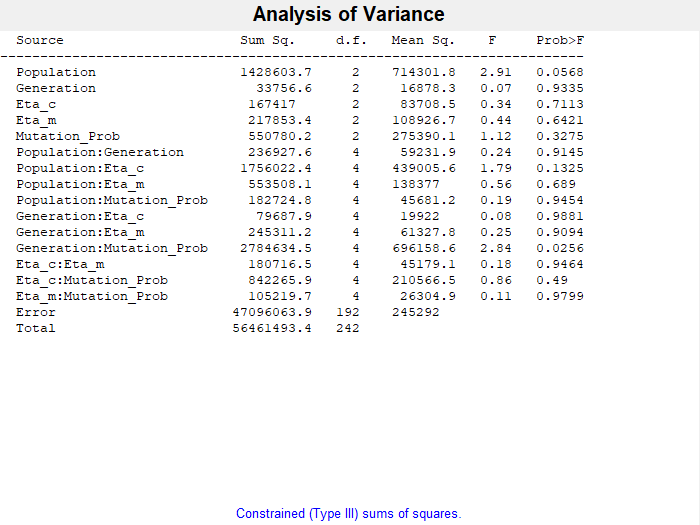

load("Fit.mat")
load("Pop.mat")
load("Gen.mat")
load("EtaC.mat")
load("EtaM.mat")
load("Mut.mat")
% Perform n-way ANOVA
[p, tbl, stats] = anovan(Fit, {Pop, Gen, EtaC, EtaM, Mut}, ...
                         'model', 'interaction', ...
                         'varnames', {'Population', 'Generation', 'Eta_c', 'Eta_m', 'Mutation_Prob'});


% Display the results
disp('ANOVA Table:');

ANOVA Table:


disp(tbl);

    {'Source'                  }    {'Sum Sq.'   }    {'d.f.'}    {'Singular?'}    {'Mean Sq.'  }    {'F'       }    {'Prob>F'  }
    {'Population'              }    {[1.4286e+06]}    {[   2]}    {[        0]}    {[7.1430e+05]}    {[  2.9120]}    {[  0.0568]}
    {'Generation'              }    {[3.3757e+04]}    {[   2]}    {[        0]}    {[1.6878e+04]}    {[  0.0688]}    {[  0.9335]}
    {'Eta_c'                   }    {[1.6742e+05]}    {[   2]}    {[        0]}    {[8.3709e+04]}    {[  0.3413]}    {[  0.7113]}
    {'Eta_m'                   }    {[2.1785e+05]}    {[   2]}    {[        0]}    {[1.0893e+05]}    {[  0.4441]}    {[  0.6421]}
    {'Mutation_Prob'           }    {[5.5078e+05]}    {[   2]}    {[        0]}    {[2.7539e+05]}    {[  1.1227]}    {[  0.3275]}
    {'Population:Generation'   }    {[2.3693e+05]}    {[   4]}    {[        0]}    {[5.9232e+04]}    {[  0.2415]}    {[  0.9145]}
    {'Population:Eta_c'        }    {[1.7560e+06]}    {[   4]}    {[        0]}    {[4.390


disp('P-values:');

P-values:


disp(p);

    0.0568
    0.9335
    0.7113
    0.6421
    0.3275
    0.9145
    0.1325
    0.6890
    0.9454
    0.9881
    0.9094
    0.0256
    0.9464
    0.4900
    0.9799




disp('stats:');
disp(stats);